# Method#3 Random Midpoint

## 隨機中點法

畫出單位圓和內接正三角形(這不太重要，應該大家都一樣)

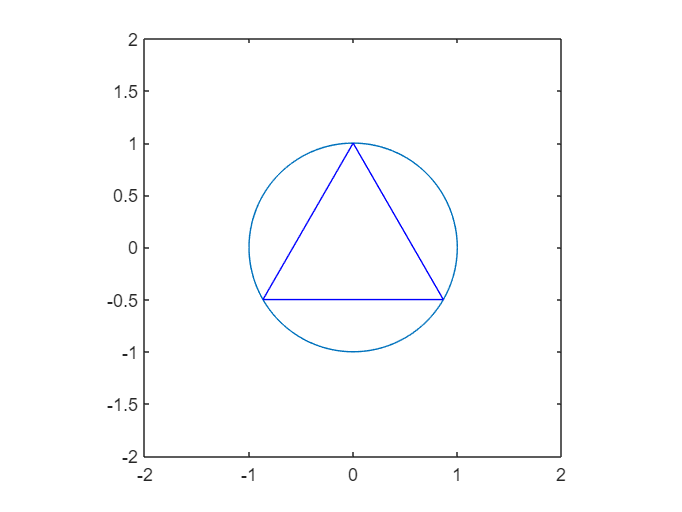

r = 1;
syms x y
fimplicit(x^2+y^2 == r^2, [-2 2, -2 2])
hold on;
axis equal;
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
plot(t(:,1),t(:,2),'b');
hold off;

a = norm(t(1,:)-t(2,:));

## Probability

計算機率

挑點

n = 100;
r_radius = sqrt(rand(n,1))*r;
r_angle = rand(n,1)*2*pi;
rx = r_radius.*cos(r_angle);
ry = r_radius.*sin(r_angle);

(1/2*b)^2 = r^2 - rx^2 - ry^2

比較專業的打法： $(\frac b2)^2 = r^2 - rx^2 - ry^2$

B = sqrt(1 - r_radius.^2)*2;
result = B>a;
sum(result)/length(result)

ans = 0.2100

## Demo

隨機中點法動畫展示

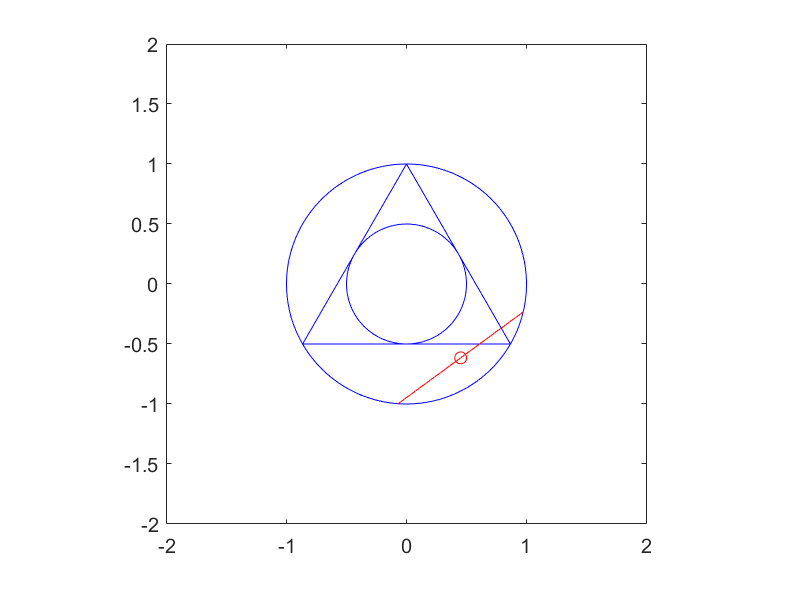

v = [-ry rx]./r_radius;
p1 = [rx ry] + 1/2*B.*v;
p2 = [rx ry] - 1/2*B.*v;
for i = 1:length(rx)
    fimplicit(x^2+y^2 == r^2, [-2 2, -2 2],'b');
    hold on;
    plot(t(:,1),t(:,2),'b-');
    fimplicit(x^2+y^2 == (r/2)^2,'b');
    plot(rx(i),ry(i),'ro');
    chord = [p1(i,:);p2(i,:)];
    plot(chord(:,1),chord(:,2),'r-');
    axis equal;
    hold off;
    pause(0.01);
end